# Save all figures into PDF

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive/Figures/Demo060521'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])

addpath([CurrentFolder '/Data'])


TargetPath = [FigurePath '/Demo062621/'];

% Go to the target folder and list all figures
cd(TargetPath)

Error using cd
Cannot CD to /home/lai-sang/Documents/GitHub/NYU-Vision-2Drive/Figures/Demo060521/Figures/Demo062621 (Name is nonexistent or not a directory).

listing = dir('*.fig');

## open and print

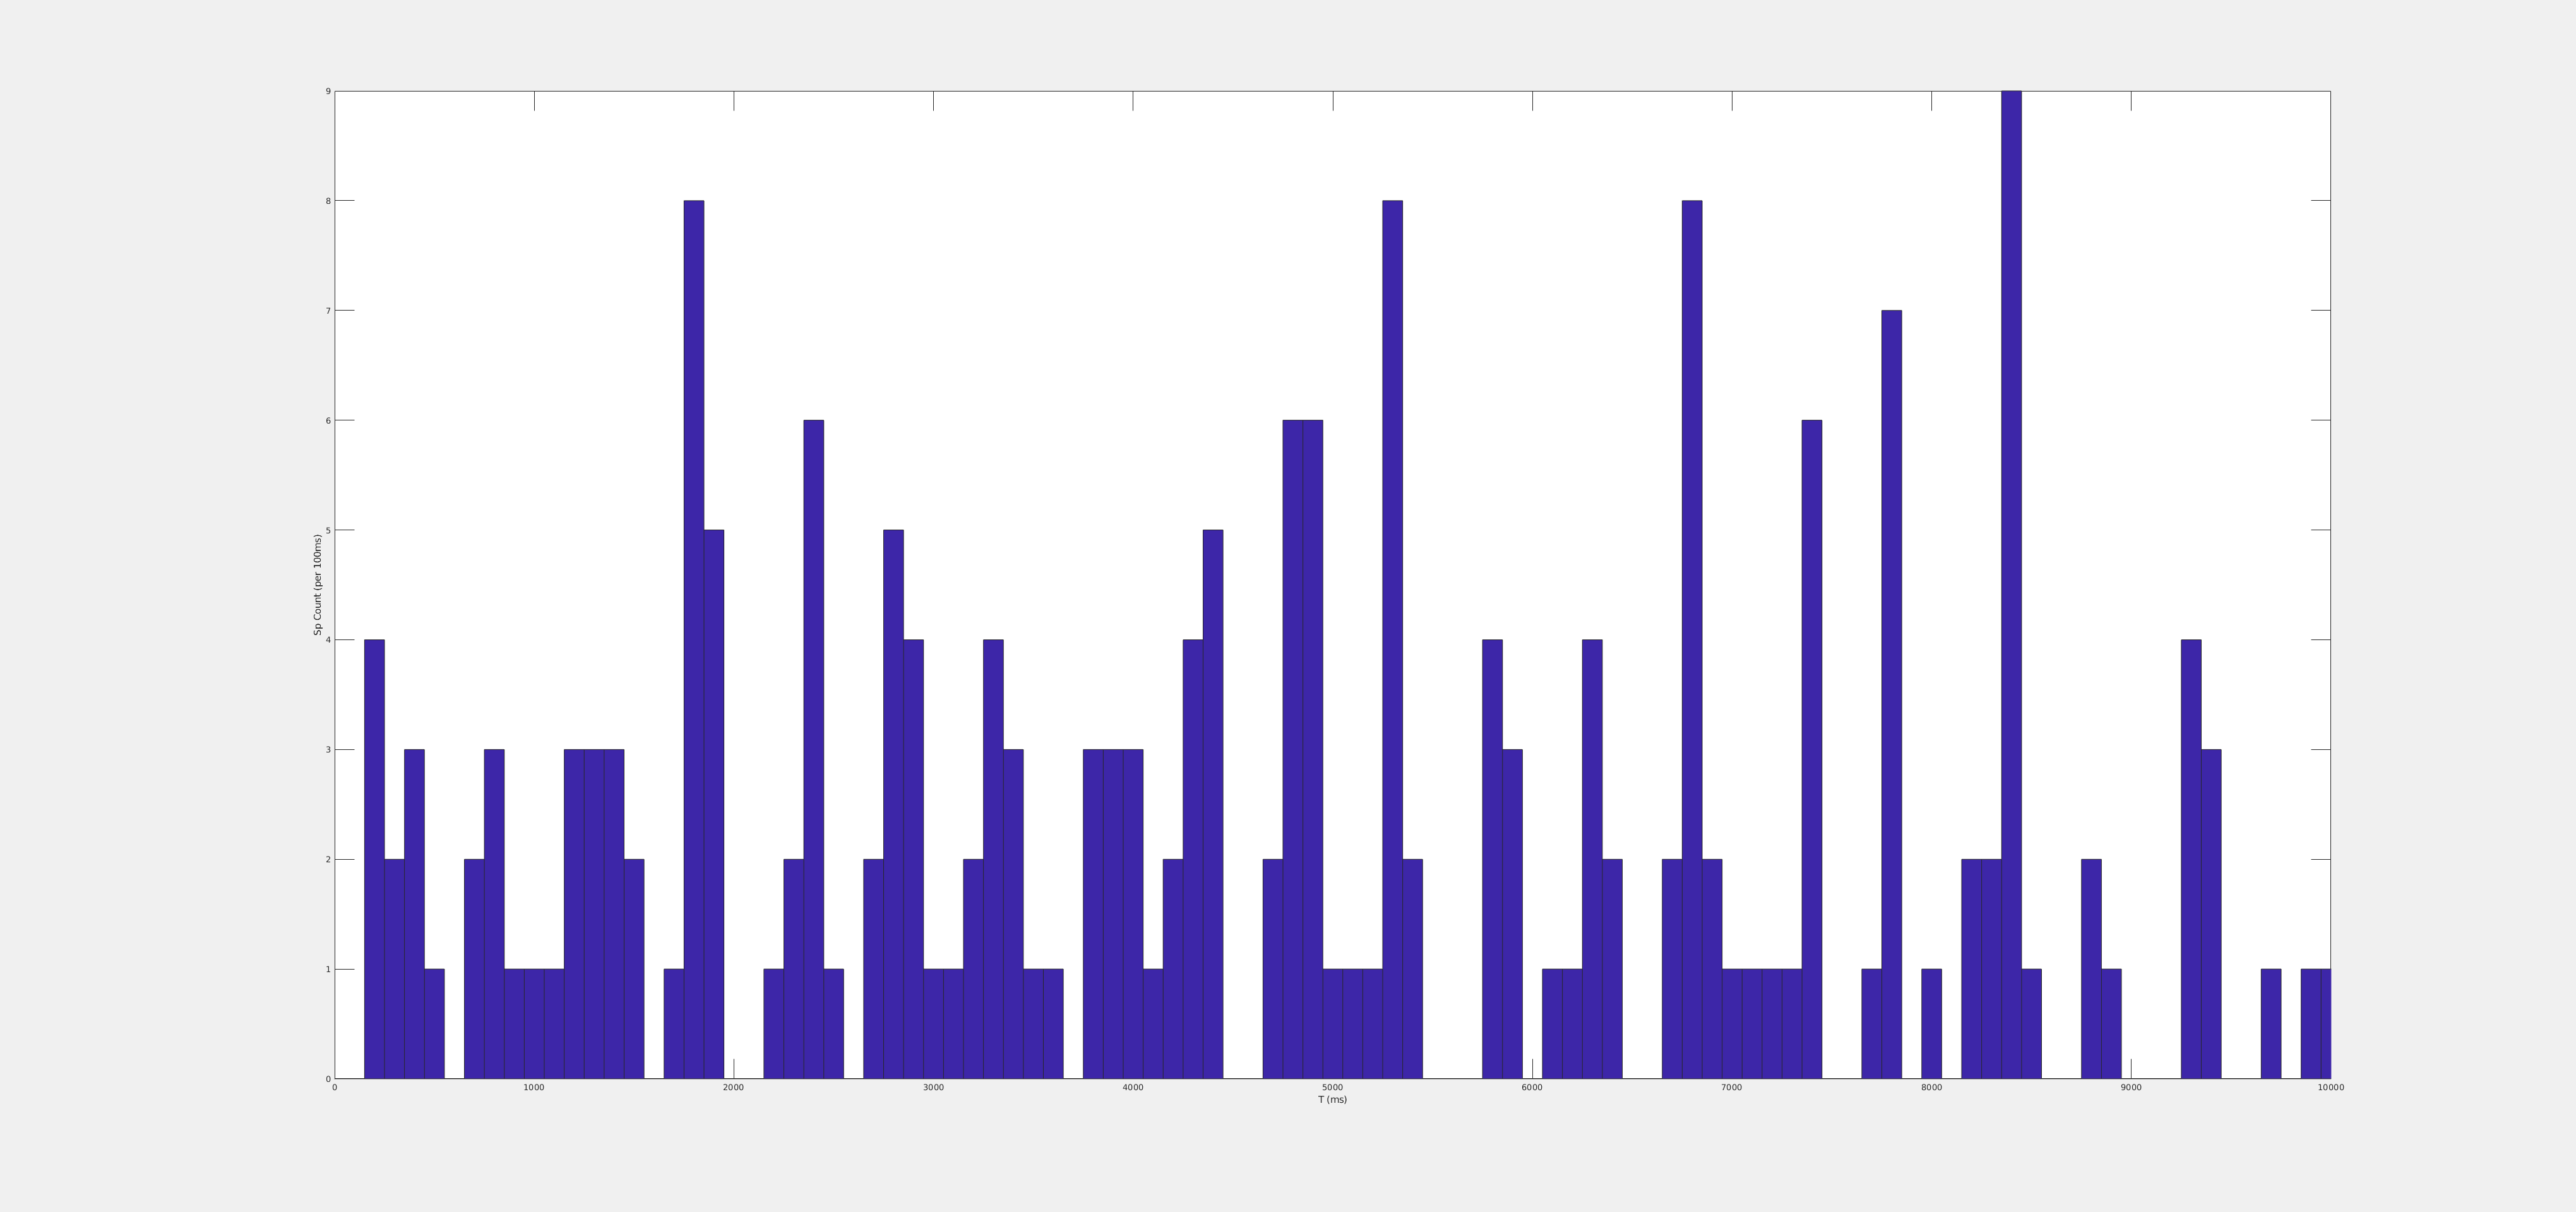

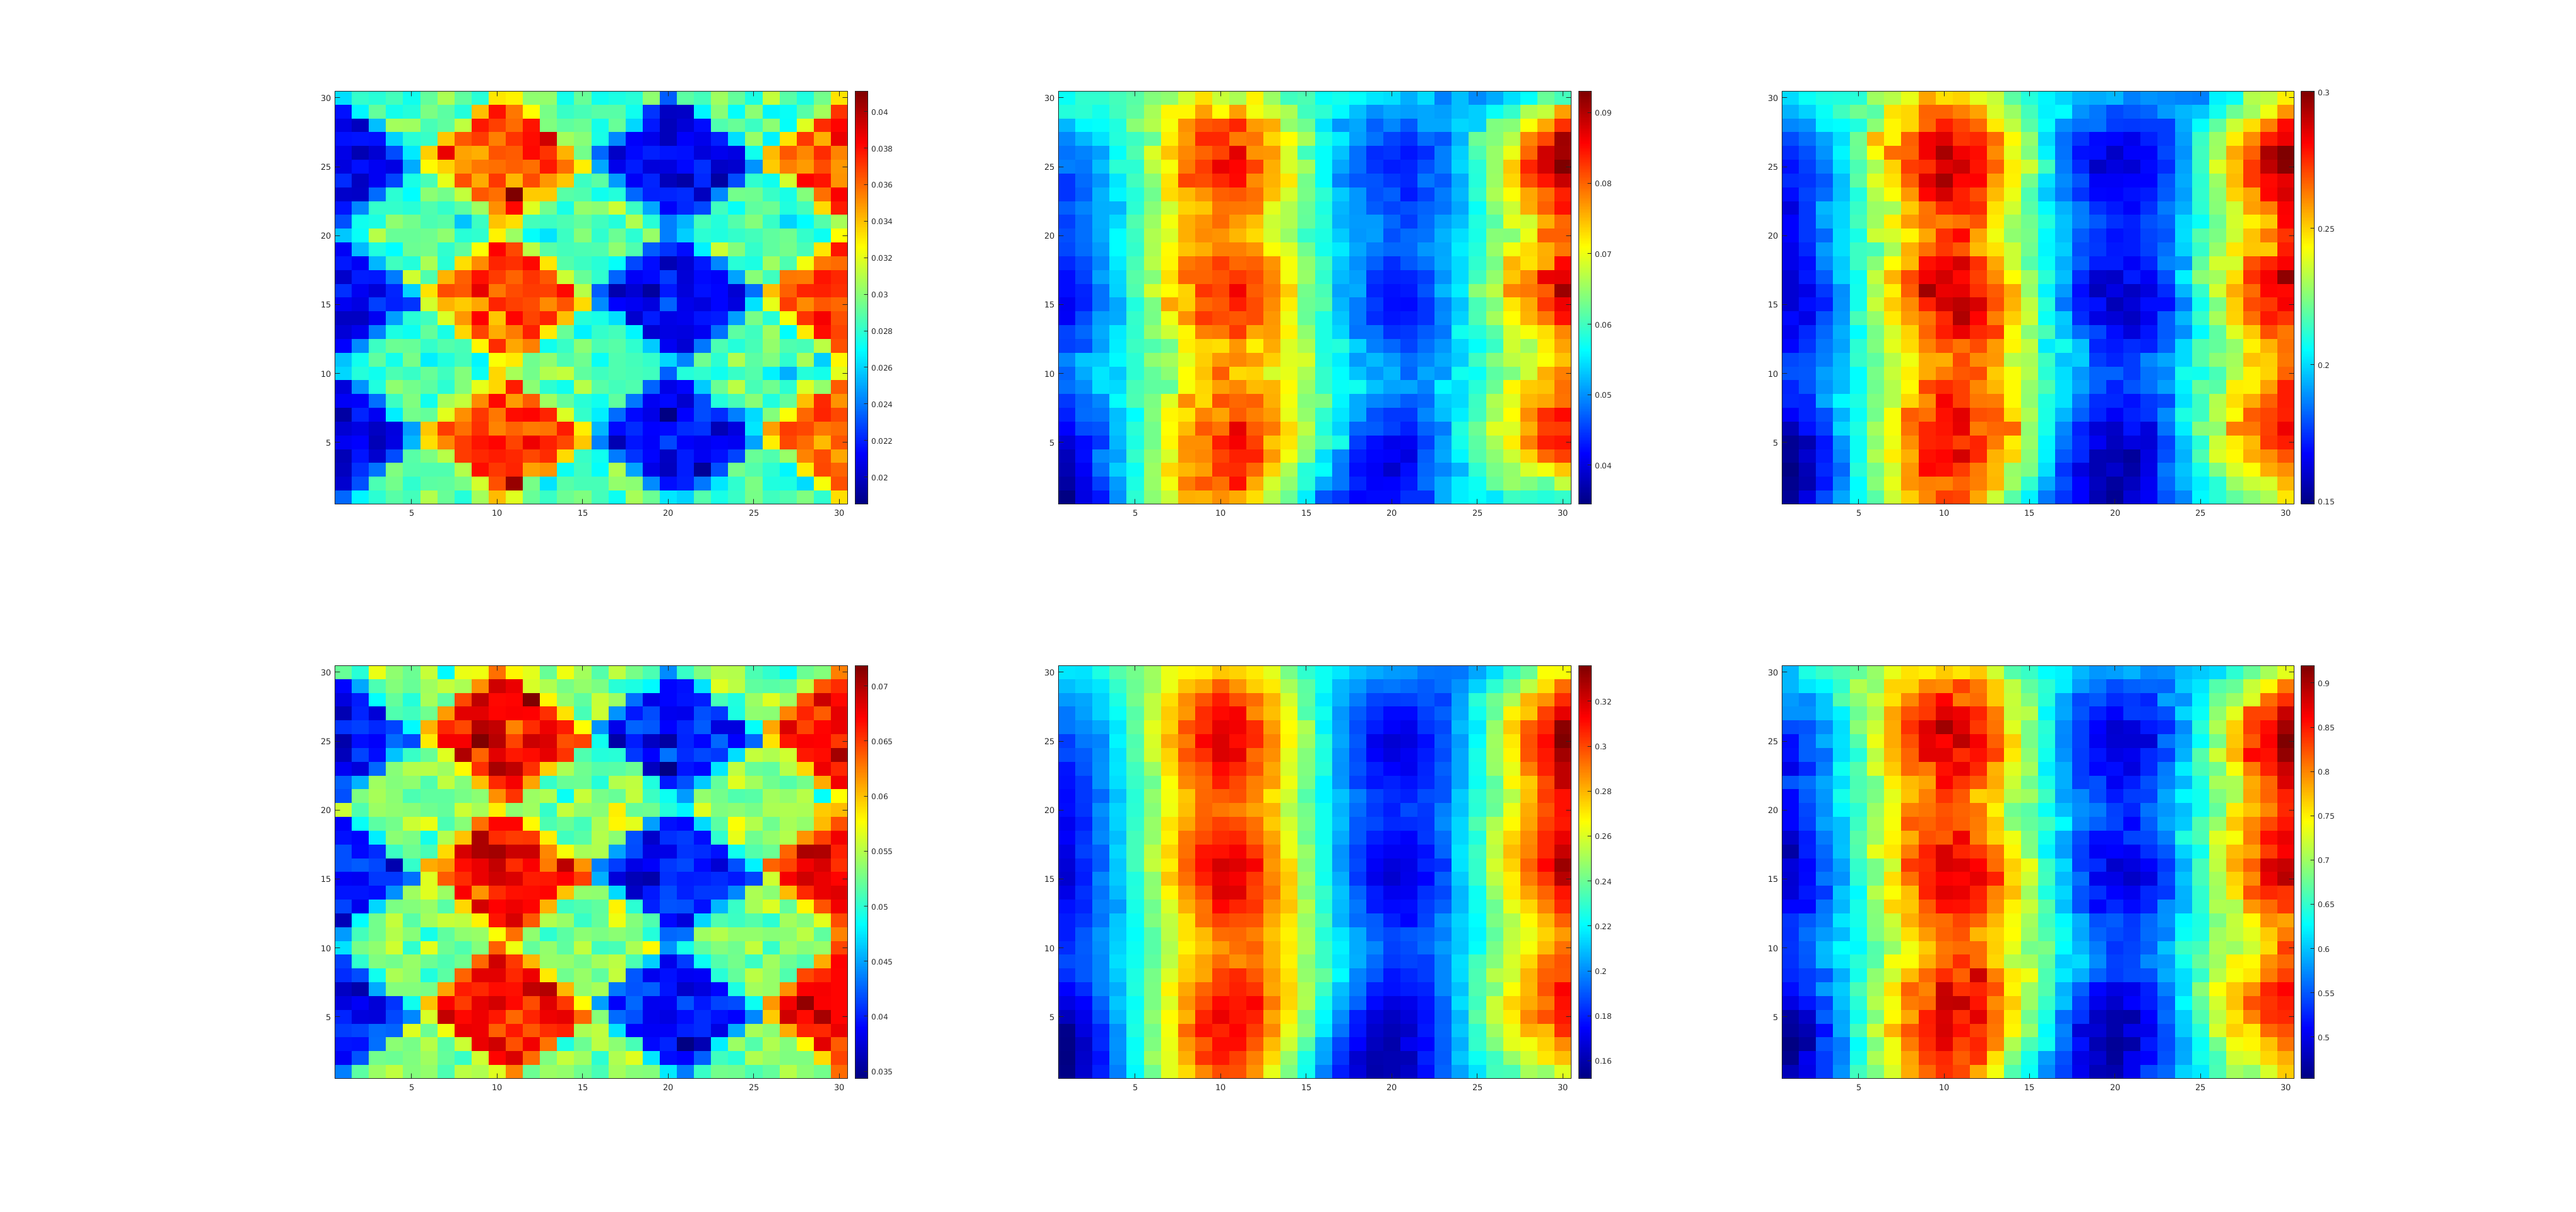

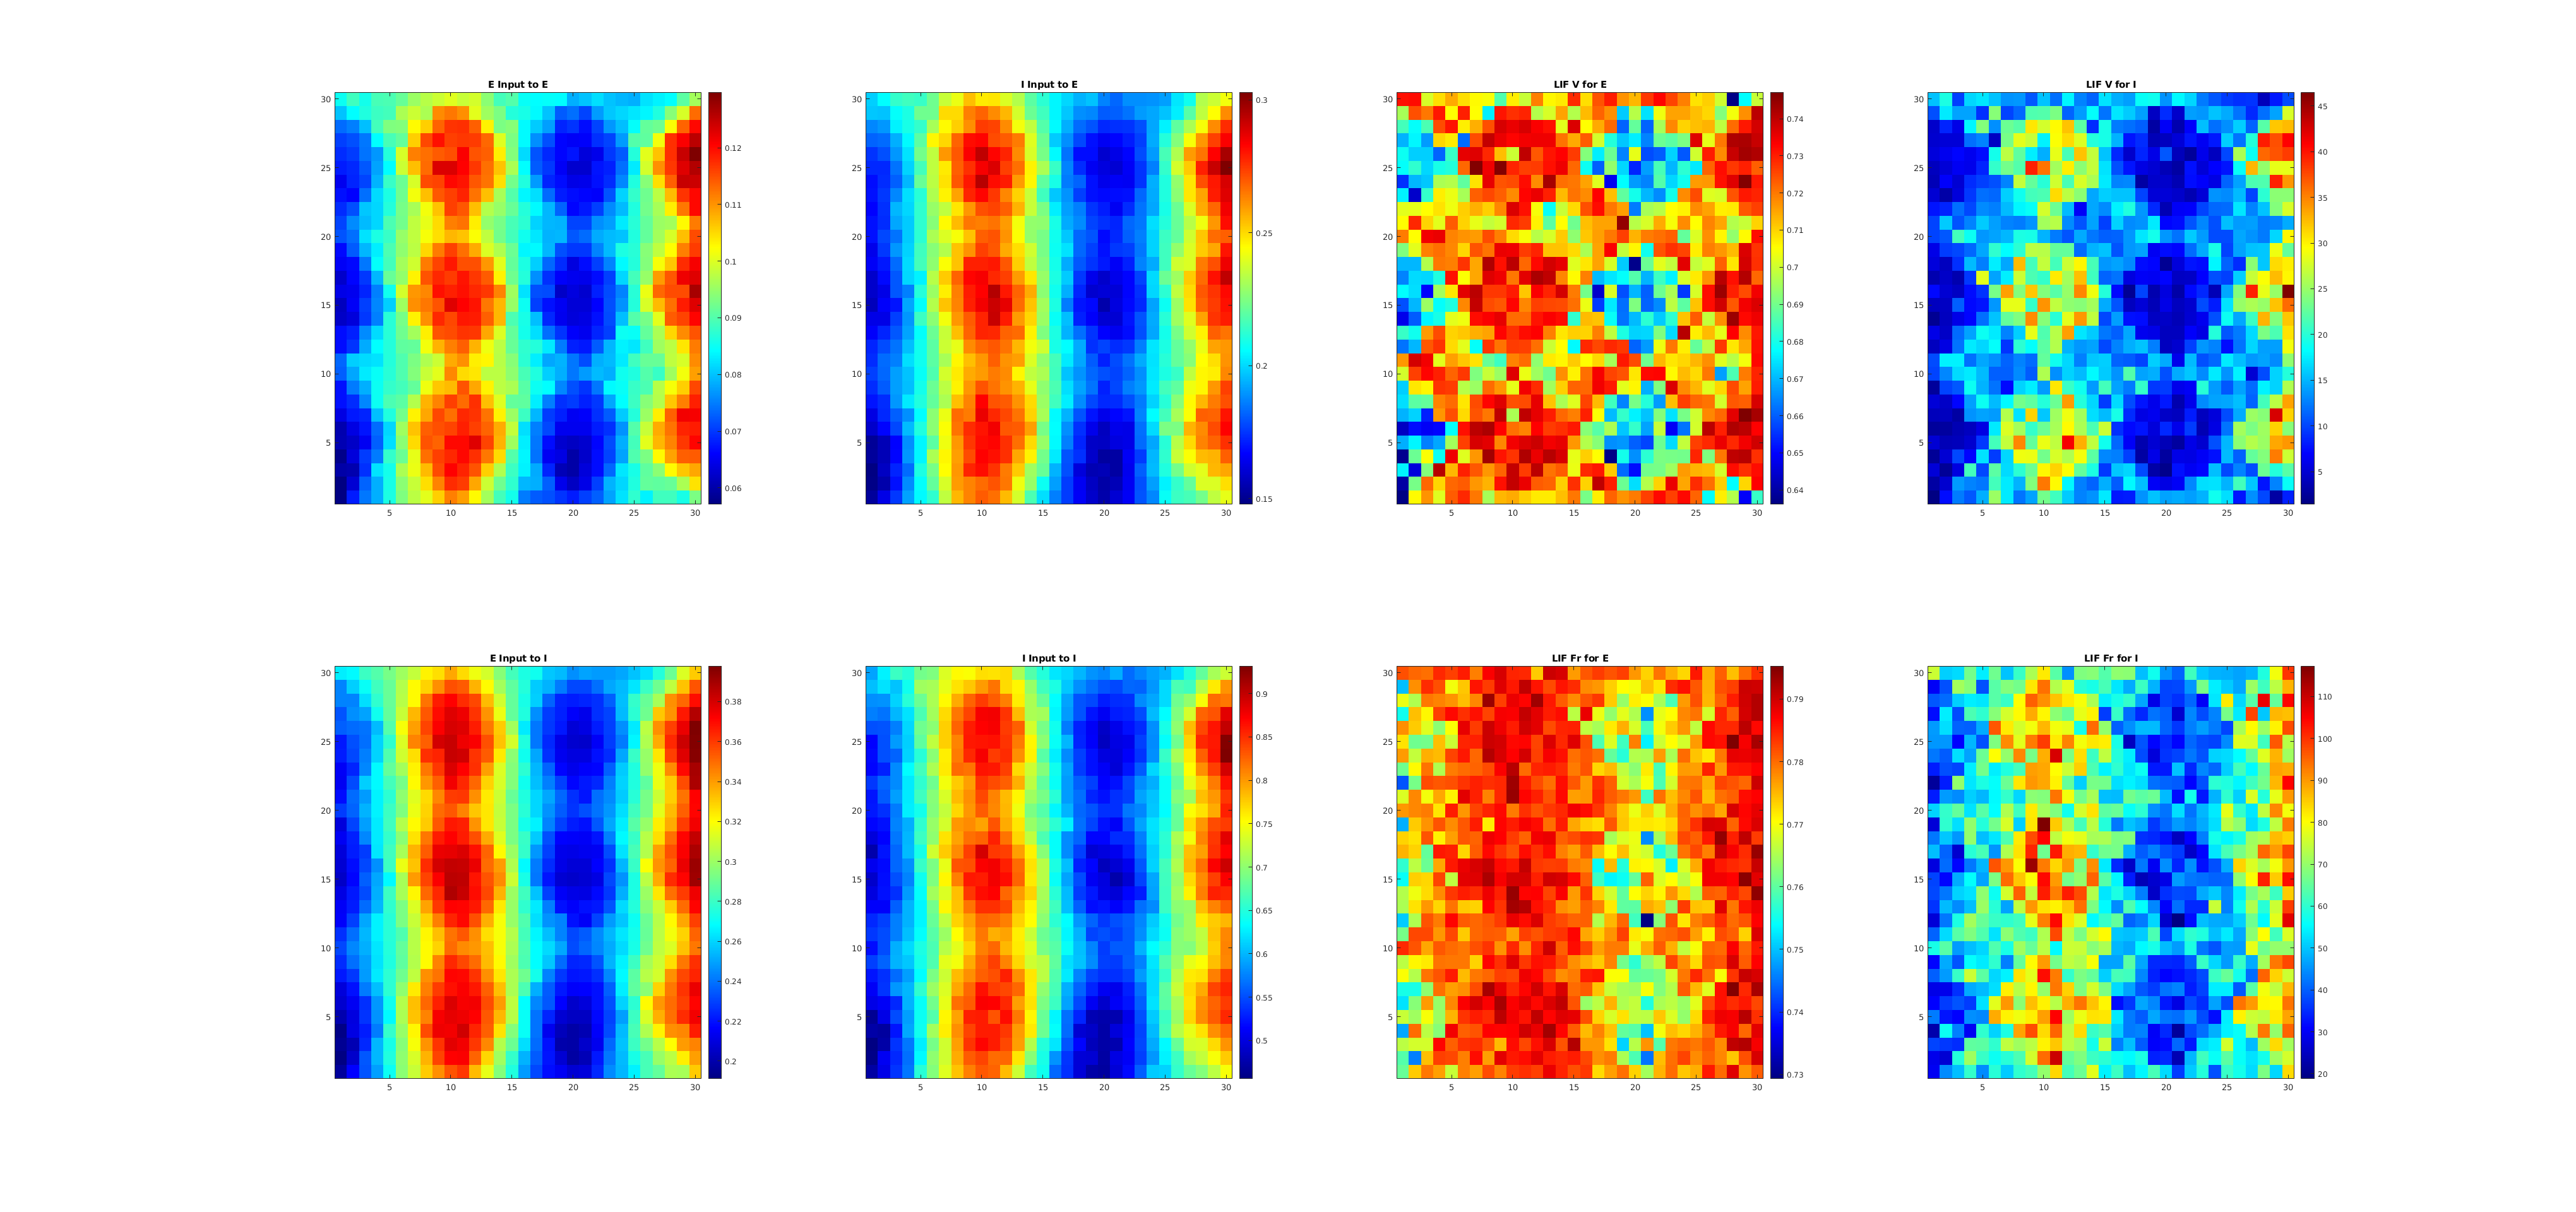

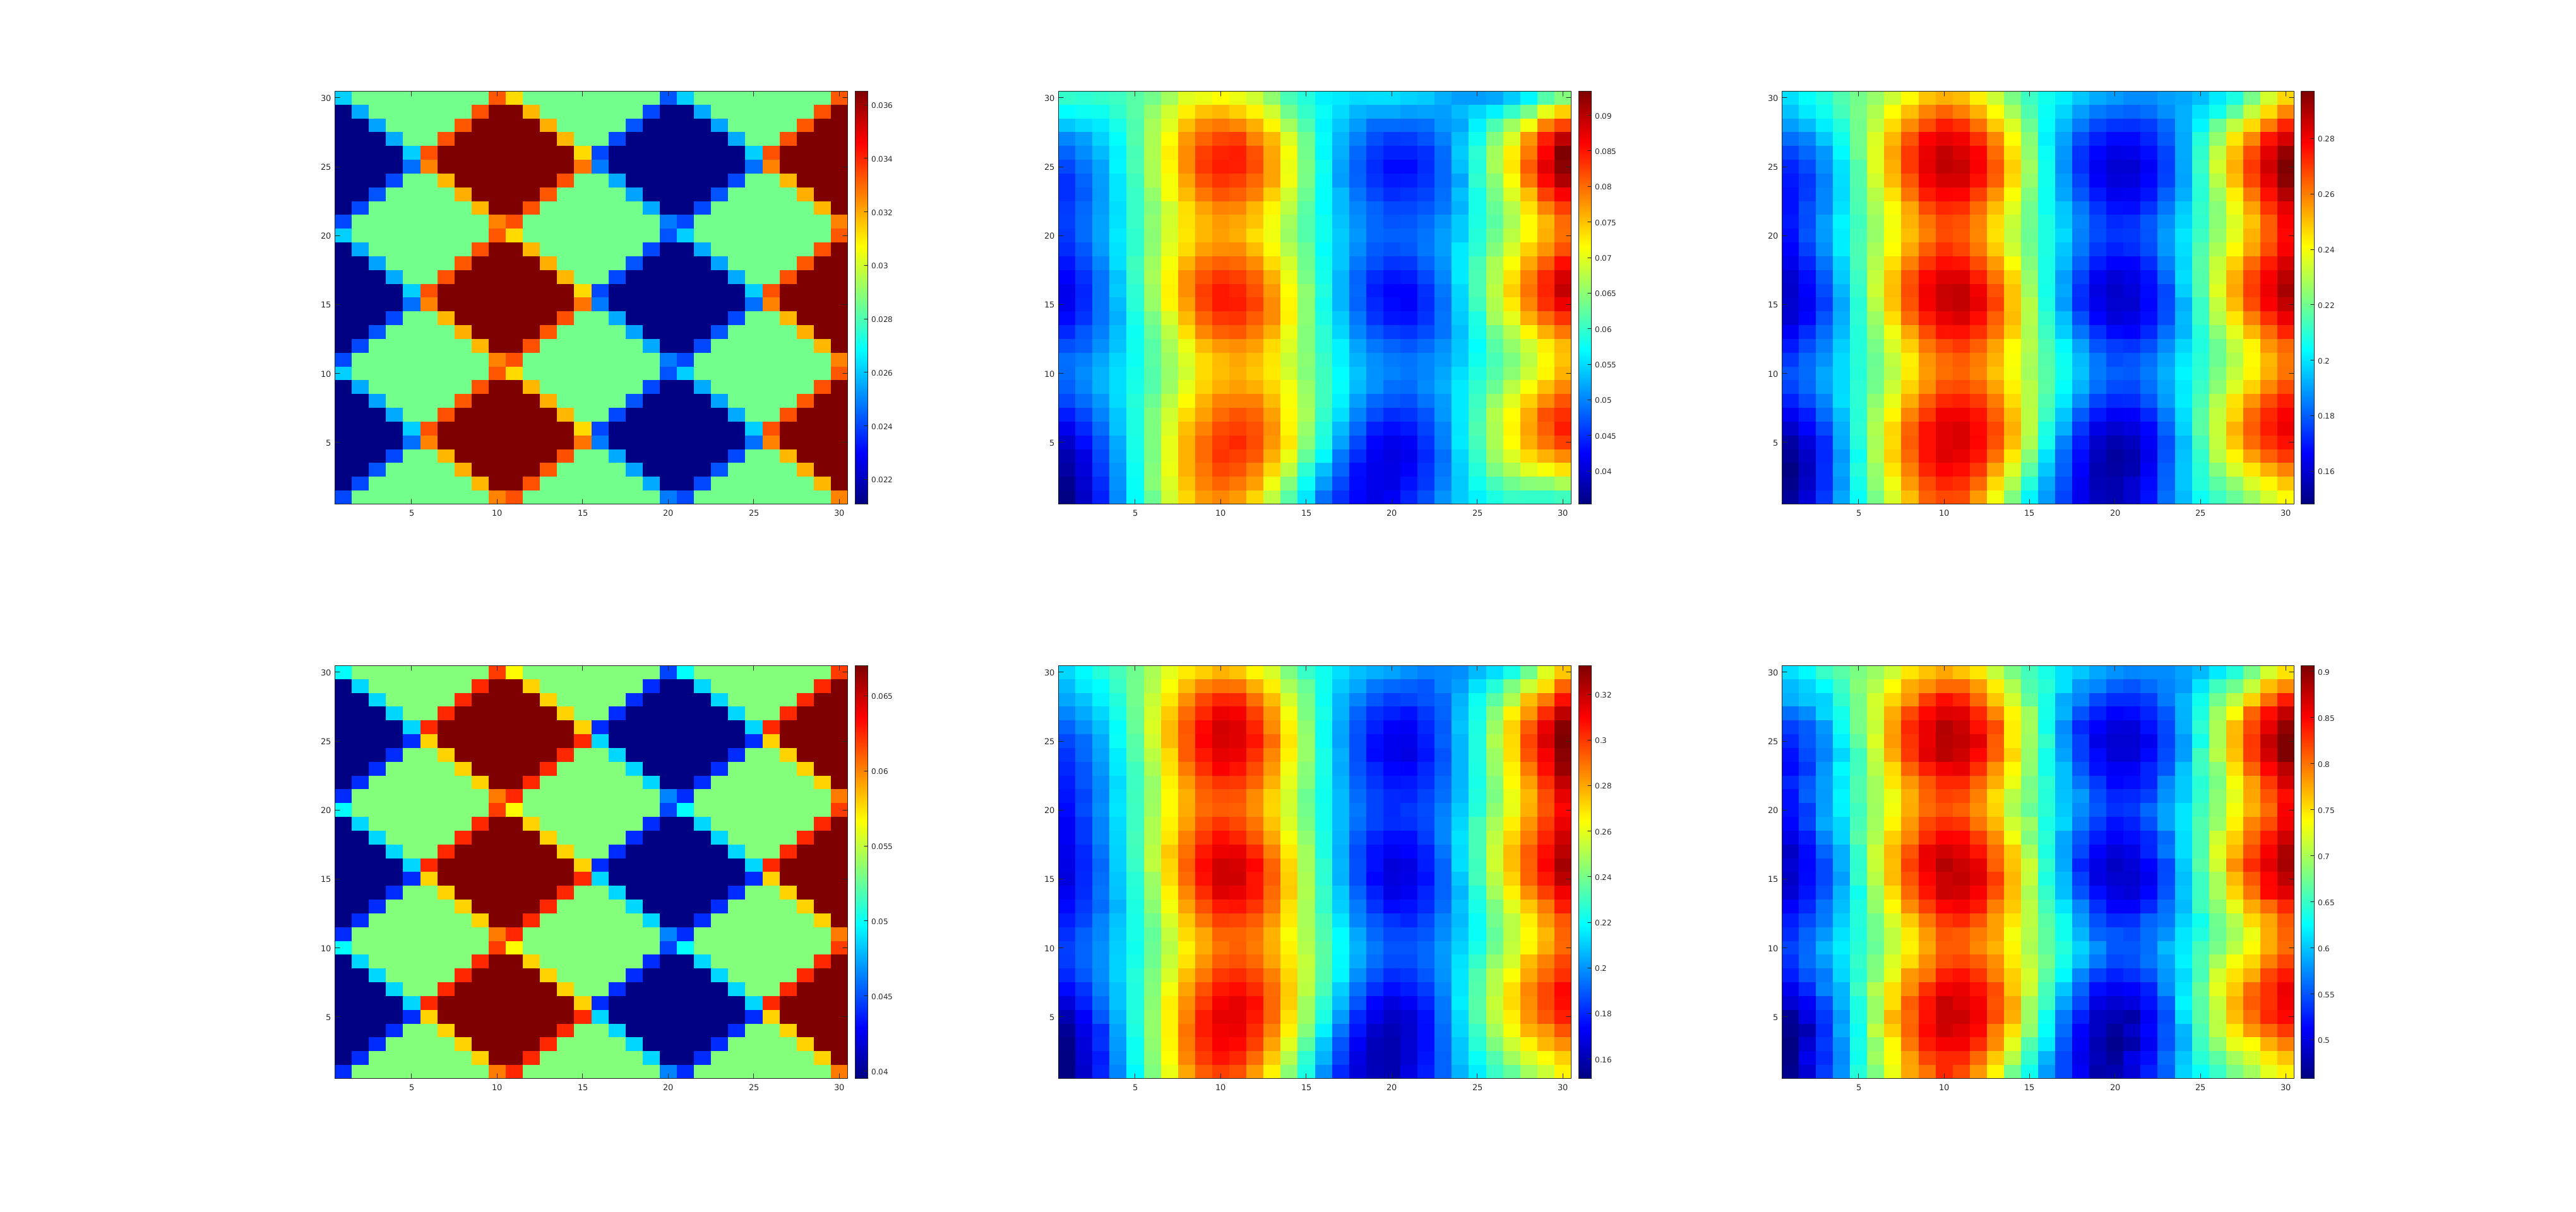

for FileInd = 1:length(listing)
    FileName = listing(FileInd).name;
    [~,name,extract]  = fileparts(FileName);
    hFig = openfig(FileName);
    set(hFig,'Units','normalized','Position',[0 0 1 1])
    exportgraphics(hFig,[name '.pdf'],'Resolution',300)
    
    close(hFig)
end